# Fordamper

clc; clear;
u = symunit;
CP = py.importlib.import_module("CoolProp.CoolProp");

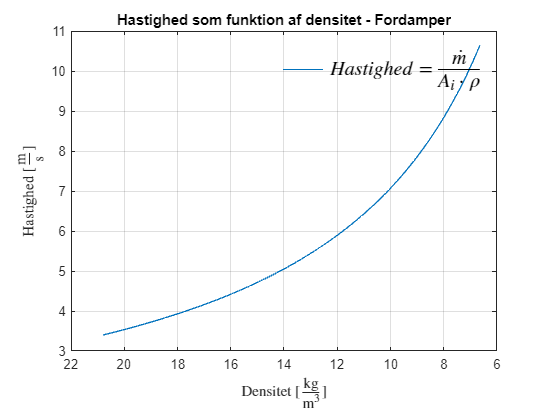

middel = "R134a";
h1 = 3.904*1e5;
h4 = 2.423*1e5; % I J/kg
p4 = 1.327*1e5; % I pascal

hlin = linspace(h4,h1,100);
plin = linspace(p4,p4,100);

qmr = 0.00338*u.kg/u.s;

A_i = 4.78*1e-5;

% Fordamper densitet og hastigheder

Ds = zeros(1, length(hlin));

for i = 1:length(hlin)
    Ds(i) = CP.PropsSI("D","H",hlin(i),"P",plin(i), middel);
end

vs_fordamp = zeros(1,length(hlin));

for h = 1:length(hlin)
    vs_fordamp(h) = separateUnits(qmr)/(Ds(h)*A_i);
end

figure
plot(Ds, vs_fordamp)

grid("on")
title("Hastighed som funktion af densitet - Fordamper")
xlabel("Densitet [$\frac{\mathrm{kg}}{\mathrm{m^3}}$]", "Interpreter","latex")
ylabel("Hastighed [$\frac{\mathrm{m}}{\mathrm{s}}$]", "Interpreter","latex")

legend("$Hastighed = \frac{\dot{m}}{A_i \cdot\rho}$","Interpreter","latex","FontSize",15,"Box","off")

set(gca, "XDir","reverse")

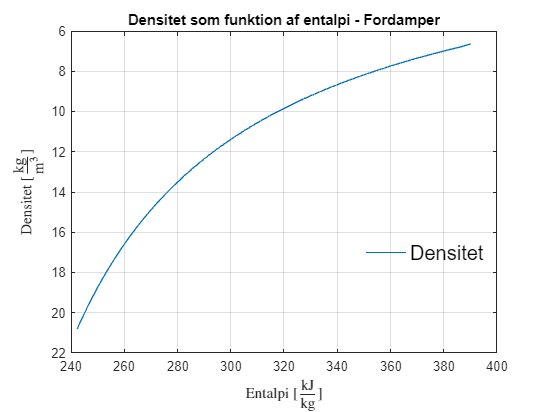


figure
plot(hlin/1e3, Ds)

grid("on")
title("Densitet som funktion af entalpi - Fordamper")
xlabel("Entalpi [$\frac{\mathrm{kJ}}{\mathrm{kg}}$]","Interpreter","latex")
ylabel("Densitet [$\frac{\mathrm{kg}}{\mathrm{m^3}}$]", "Interpreter","latex")

legend("Densitet","location","best","FontSize",15,"box","off")

set(gca, "YDir","reverse")


% 
% Ts = zeros(1,length(hlin));
% 
% for j = 1:length(hlin)
%     Ts(i) = CP.PropsSI("T","D",Ds(j), "P",plin(j), middel);
%     
% end

v_ud_fordamp = max(vs_fordamp)

v_ud_fordamp = 10.6630

rho_ud_fordamp = min(Ds)

rho_ud_fordamp = 6.6315

v_ind_fordamp = min(vs_fordamp)

v_ind_fordamp = 3.3976

rho_ind_fordamp = max(Ds)

rho_ind_fordamp = 20.8122

## Energi i løbet af fordamper

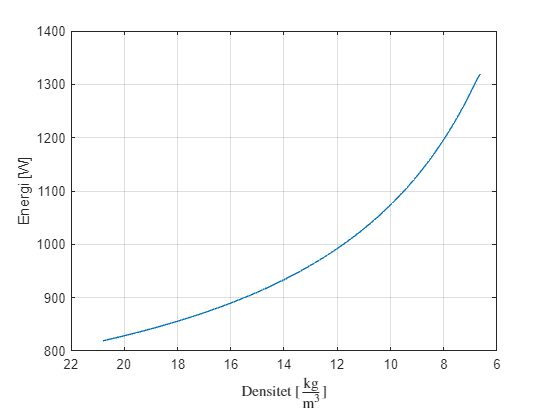

hs_units = hlin.*u.J/u.kg;

W_fordamp = vpa(qmr.*hs_units,6);

Wfordamp_plot = separateUnits(W_fordamp);

figure
plot(Ds, Wfordamp_plot)

grid("on")
ylabel("Energi [W]")
xlabel("Densitet [$\frac{\mathrm{kg}}{\mathrm{m^3}}$]", "Interpreter","latex")
set(gca, "XDir","reverse")



kond_ror = 7*u.m; % meter
vs_units = vpa(mean(vs_fordamp)*u.m/u.s,4)

$$vs\_units = 7.006\,\frac{m}{s}$$


t_i_ror = vpa(kond_ror/vs_units,4)

$$t\_i\_ror = 0.9991\,s$$



fordamp_Wdiff = max(Wfordamp_plot) - min(Wfordamp_plot);



fordamp_W_eff = fordamp_Wdiff*(u.J/u.s);%*t_i_ror;
fordamp_W_eff = vpa(unitConvert(fordamp_W_eff,"SI","Derived"),4)

$$fordamp\_W\_eff = 500.6\,W$$



% 500 watt
% Hvor meget energi er der i saltvandsblandingen? Det er nødvendigt at
% vide, for at finde ud af hvor lang tid det vil tage at køle ned 
% Modstande skal inkluderes


# Beregninger til brine

CPvand = vpa(CP.PropsSI("C","T",293.15,"Q",0,"Water"),3)*u.J/(u.kg*u.K)

$$CPvand = 4184.3605144023895263671875\,\frac{J}{K\,\mathrm{kg}}$$

CPsalt = 0.853 * u.J/(u.g*u.K);
CPsalt = unitConvert(CPsalt,u.J/(u.kg*u.K))

$$CPsalt = 853\,\frac{J}{K\,\mathrm{kg}}$$



CPbrine = 0.75*CPvand + 0.25*CPsalt;
dT = 30*u.K;
mbrine = 20*u.kg;

Ebrine = mbrine*dT*CPbrine;

unitConvert(Ebrine/fordamp_W_eff,u.min)

$$ans = 66.953010036434519615166169107677\,\min$$

# Vægtemperaturer ved rør

ry = 4.1*u.mm;
ri = 4*u.mm;
alpha_brine = 1507*u.W/(u.m^2*u.K);
lambda = 372 * u.W/(u.m*u.K);
L = 7*u.m;
A = unitConvert(2*pi*ri*L,"SI");
syms tv
tfl = -10*u.K;
ti = -20*u.K;
phi = fordamp_W_eff;

eq2 = phi == alpha_brine*A*(tfl - tv);

%vpa(solve(eq, tv),3)



eq = alpha_brine*A*(tfl - tv) == lambda*2*pi*L*(ti - tv)/(log(ri/ry));

vpa(solve(eq, tv))

$$ans = -19.9960003350845452490087595866\,K$$

lambda_luft = vpa(CP.PropsSI("L","T",253.15,"P",plin(1),"R134a")*u.W/(u.m*u.K),4)

$$lambda\_luft = 0.009816\,\frac{W}{K\,m}$$


di = unitConvert(8*u.mm,"SI");
du = unitConvert(8.2*u.mm,"SI");
alpha_middel = 1470 *u.W/(u.m^2*u.K);
alpha_brine = 1507 * u.W/(u.m^2*u.K);
lambda_kobber = 372 * u.W/(u.m*u.K);

%U_u = vpa(1/(1/(alpha_brine+alpha_middel) + log(du/di)/(2*pi*lambda_kobber) * pi*du))

U_u = vpa(1/(1/(alpha_middel) * du/di + du/(2*lambda_kobber)*log(du/di) + 1/alpha_brine),3)

$$U\_u = 735.0\,\frac{W}{K\,m^{2}}$$


L = 6.7*u.m;
Au = du*pi*L;
tfi = -20*u.K;
tfu = -10*u.K;
phi = vpa(U_u*Au*(tfi - tfu),3)

$$phi = -1270.0\,W$$


vpa(tfu - phi/((alpha_middel+alpha_brine)*Au))

$$ans = -7.5321178934851916940697470279339\,K$$

% nu = 0.000001511; %m^2 / s
% 
% D_fordamp = CP.PropsSI("D","T",253.15,"P",plin(1),middel)*u.kg/u.m^3
% dyn_vis_eta = CP.PropsSI("V","T",273.15,"P",plin(1),middel)*u.Pa*u.s
% kin_vis_nu = vpa(unitConvert(dyn_vis_eta/D_fordamp,"SI","Derived"),4)
% 
% qmr = 0.00338*u.kg/u.s
% 
% d_1 = vpa(di,3) % m %indre diameter af kobber rør
% 
% g = 9.82 * u.m/u.s^2
% 
% lambda_1 = CP.PropsSI("L","T",253.15,"P",plin(1),middel)
% 
% r_fordamp = 211.2 * 1000 * u.J/u.kg%m * l_fd
% 
% 
% 
% Re_1 = vpa(unitConvert(qmr * d_1 / (pi/4 * d_1^2 * dyn_vis_eta),"SI","Derived"),3)
% 
% K_f = vpa(unitConvert(r_fordamp / (L * g),"SI"),3)
% 
% NUs_1 = 0.0075 * (Re_1^2 * K_f )^0.40
% 
% alpha_1 = NUs_1 * lambda_1 / d_1;
% alpha_1_ = vpa(alpha_1,3)






